## **TASK 1_Part 1**

$\begin{array}{l}
\overset{\ldotp }{x} =\mathrm{Ax}+\mathrm{Bu}\\
y=\mathrm{Cx}+\mathrm{Du}
\end{array}$     (y is output and u is input, $x=\left\lbrack \begin{array}{c}
q\\
\overset{\ldotp }{q} 
\end{array}\right\rbrack$ )

% Variables
clear; clc;
mc = 1.5; mp = 0.5; g = 9.82; L = 1; d1 = 0.01; d2 = 0.01;
x0 = [0; (10*pi)/180; 0; 0]

x0 =          0
    0.1745
         0
         0


% Defining A and B matrix

a32 = (g*mp)/mc; a33 = -(d1/mc); a34 = -(d2/(L*mc));
a42 = (g*(mc+mp))/(L*mc); a43 = -d1/(L*mc); a44 = -((d2*(mc+mp))/(L*L*mc*mp));
A = [0 0 1 0;
    0 0 0 1;
    0 a32 a33 a34;
    0 a42 a43 a44];
B = [0; 0; 1/mc; 1/(L*mc)];
clear a32 a33 a34 a42 a43 a44;
clear mc mp g L d1 d2;

% If q1(x) and q2(theta) both are output
% Then, C = [1 0 0 0; 0 1 0 0]; D = [0; 0];
% But here, only q2(theta) is the output, So...

C = [0 1 0 0]; D = 0;
sys = ss(A,B,C,D)


sys =
 
  A = 
              x1         x2         x3         x4
   x1          0          0          1          0
   x2          0          0          0          1
   x3          0      3.273  -0.006667  -0.006667
   x4          0      13.09  -0.006667   -0.02667
 
  B = 
           u1
   x1       0
   x2       0
   x3  0.6667
   x4  0.6667
 
  C = 
       x1  x2  x3  x4
   y1   0   1   0   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



## **TASK 1_Part 2**


$$\mathrm{For}\;\overset{\ldotp }{x\;} =\mathrm{Ax}$$



$$x\left(t\right)={{\mathrm{Te}}^{\mathrm{Dt}} T}^{-1} \;x\left(0\right)$$


To have stability the exponent term must converge to zero. Therefore, D matrix (eigenvalues) must be negative

%Eigen Values 
[T,D_eig] = eig(A); 
% D_eig is diagonal matrix of eigenvalues and T is vector matrix of eigen vectors
eig_values = eig(A)

eig_values =          0
   -3.6327
    3.6043
   -0.0050


%Pole 
pole_sys = pole(sys)

pole_sys =    -3.6327
    3.6043
   -0.0050
         0


[Z, gain] = zero(sys)

Z = 	1.0e+-19 *

    0.8809
         0


gain = 0.6667

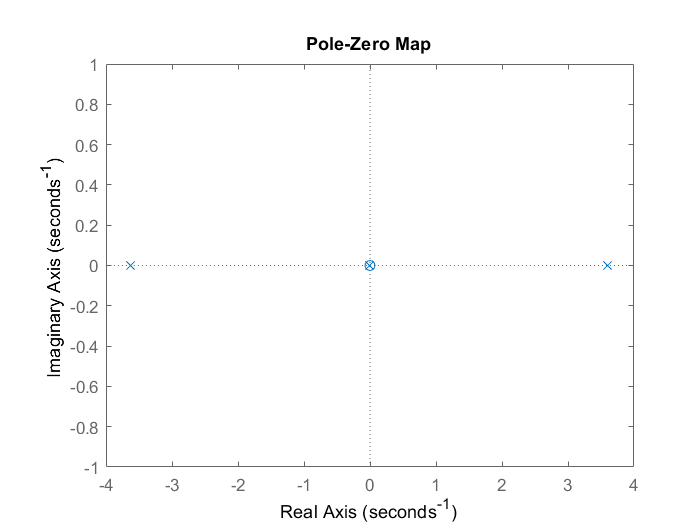

pzmap(sys)

## TASK 1_Part 3

sys_tf = tf(sys)


sys_tf =
 
          0.6667 s - 5.873e-20
  -------------------------------------
  s^3 + 0.03333 s^2 - 13.09 s - 0.06547
 
Continuous-time transfer function.



[a, b] = ss2tf(A,B,C,D)

a =          0         0    0.6667    0.0000    0.0000


b =     1.0000    0.0333  -13.0932   -0.0655         0


zsys = zpk(sys)


zsys =
 
            0.66667 s
  -----------------------------
  (s+3.633) (s-3.604) (s+0.005)
 
Continuous-time zero/pole/gain model.

